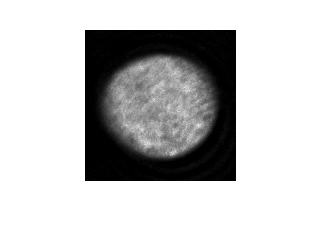

% Load image data from defringed file called OD_image
rect = [131,267,150,150];
crop_rect = [rect(1) - rect(3)/2, rect(2) - rect(4)/2, rect(3), rect(4)];
images = zeros(rect(3)+1, rect(4)+1, size(OD_image,3));

for i = 1:size(OD_image,3)
    temp = OD_image(:,:,i);
    images(:,:,i) = imcrop(temp,crop_rect);
end



% Average
counter = 0;
threshhold =2000; 
averageimage = zeros(rect(3)+1,rect(4)+1);

for i = 1:size(images,3)
    if sum(sum(images(:,:,i))) > threshhold &i~=8&i~=10&i~=33&i~=35&i~=42&i~=43&i~=47&i~=48&i~=54&i~=59&i~=67
        counter = counter + 1;
        averageimage = averageimage + images(:,:,i);
    end
end
averageimage = averageimage / counter;

figure; imshow(averageimage,[0 3]);

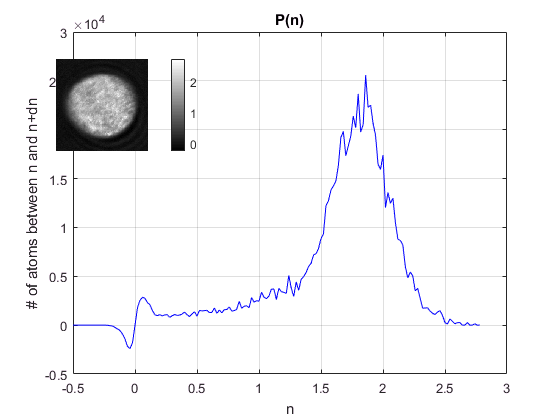


[n_i_de,P_n_de] = extract_Pn(averageimage,'plot',1,'plot_nxy_pos',[0.1 0.6 0.3 0.3],'n_i',n_i_edges);

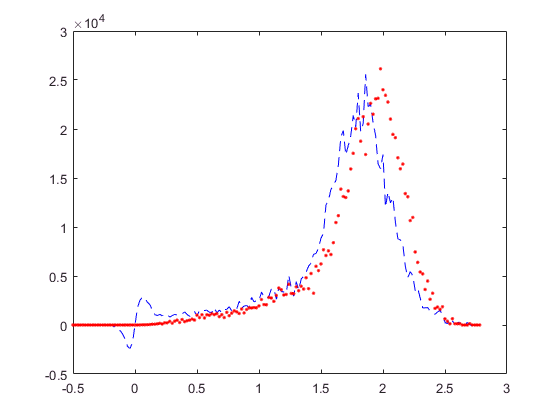


figure;
plot(n_i_de,P_n_de,'b--',n_i_original,P_n_original,'r.');